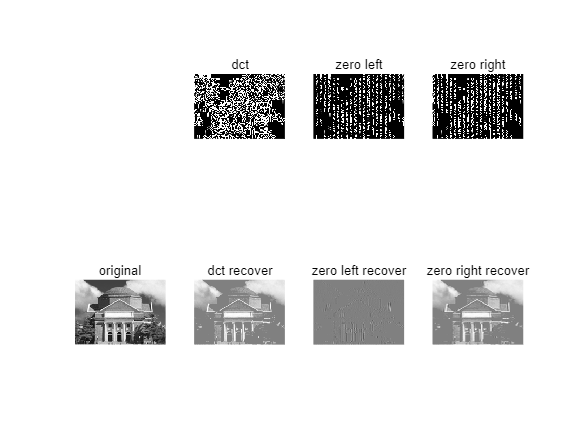

%Ch2_3.mlx
%block processing recovery; zero left/right
load JpegCoeff.mat;
load hall.mat;
raw=hall_gray;
%reference:https://www.mathworks.com/help/images/distinct-block-processing.html
%normal, zero left half, zero right half.
dct_n=@(block_struct) dct_normal(block_struct.data);
dct_l=@(block_struct) dct_zero_left(block_struct.data);
dct_r=@(block_struct) dct_zero_right(block_struct.data);
%inverse transform
idct_n=@(block_struct) idct_normal(block_struct.data);
%coefficient matrices
C=blockproc(raw,[8,8],dct_n);
C_l=blockproc(raw,[8,8],dct_l);
C_r=blockproc(raw,[8,8],dct_r);
%recovered matrices
R=blockproc(C,[8,8],idct_n);
R_l=blockproc(C_l,[8,8],idct_n);
R_r=blockproc(C_r,[8,8],idct_n);

%start to plot...
figure;

subplot(2,4,5);
imshow(raw);
title("original");

subplot(2,4,2);
imshow(C);
title("dct");

subplot(2,4,3);
imshow(C_l);
title("zero left");

subplot(2,4,4);
imshow(C_r);
title("zero right");

subplot(2,4,6);
imshow(R);
title("dct recover");

subplot(2,4,7);
imshow(R_l);
title("zero left recover");

subplot(2,4,8);
imshow(R_r);
title("zero right recover");

function C=dct_normal(P)
C=dct2(double(P-128));
end

function C=dct_zero_left(P)
C=dct2(double(P-128));
C(:,1:4)=0;
end

function C=dct_zero_right(P)
C=dct2(double(P-128));
C(:,end-3:end)=0;
end

function P=idct_normal(C)
P=uint8(idct2(C)+128);
end
